# Asquire

Task**:  Validation of Asquire Data (VAD)**

audio_files = dir("data");
audio_files(1:2)=[]

audio_files = 16×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


#### **Fricatives**

#### 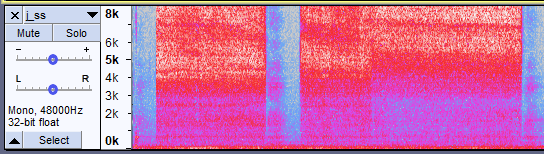 

Fig.1 example spectrum for "sss"

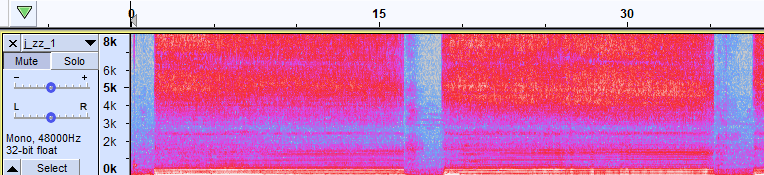

Fig.2 example spectrum for "zzz"

Obv: **High energy at 5k to 6k**

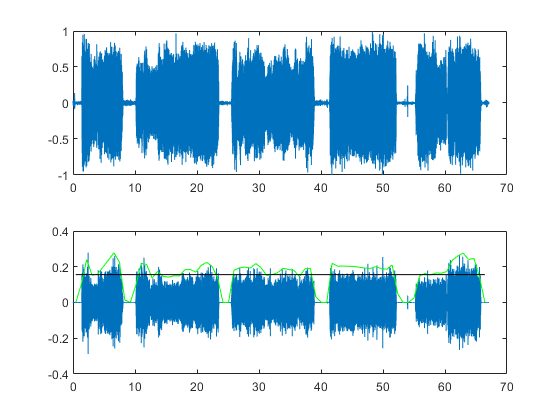

count_fric = 5


audio_file = audio_files(7).name;

startFreq = 5000;
endFreq   = 6000;
engwinp   = 0.88;
thrp      = 0.56;

r.start = startFreq;
r.end = endFreq;

count_fric = countStimsL(audio_file, r, engwinp, thrp)

#### **Vowels**

- **"aaa" and others**

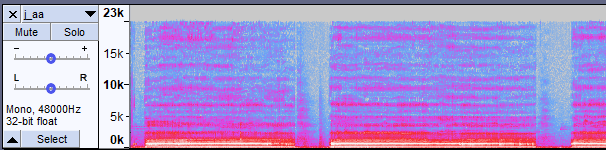

Fig.3 example spectrum for "aaa"

Obv: **High energy at 200 to 1k**

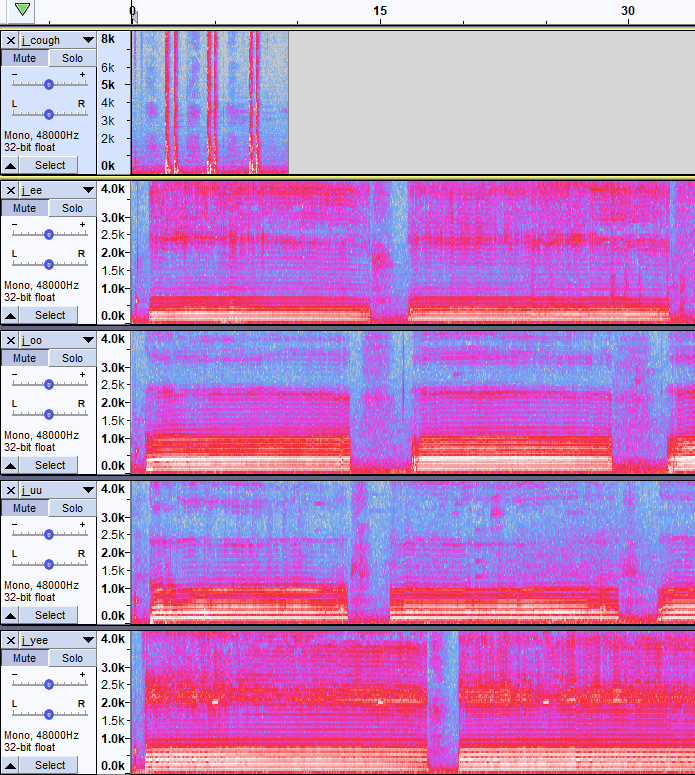

Fig.4 example spectrum for other vowels

Obv: **High energy at 200 to 1k**

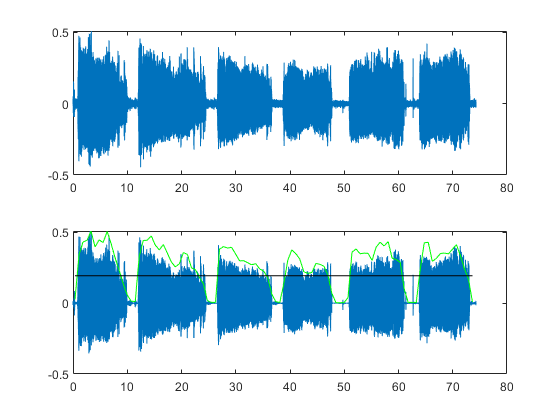

count_vowel = 6

audio_file = audio_files(1).name;

startFreq = 200;
endFreq   = 5000;
engwinp   = 0.74;
thrp      = 0.38;

r.start = startFreq;
r.end = endFreq;

count_vowel = countStimsL(audio_file, r, engwinp, thrp)